clc; clear; close all
rng(1);

% Generate x,p,u
P = 12; % Number of nodes
theta = GenThetaMat(P,'random');
x0 = GenStateVec(P, 'random');
p = GenPStruct(P, theta);
u0 = GenInputVec(P, 5); % Linearization operating point, t=0
disp('Linearization about')

Linearization about


x0, u0

x0 = 12×1 cell array
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}


u0 = 12×1 cell array
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}
    {4×1 double}


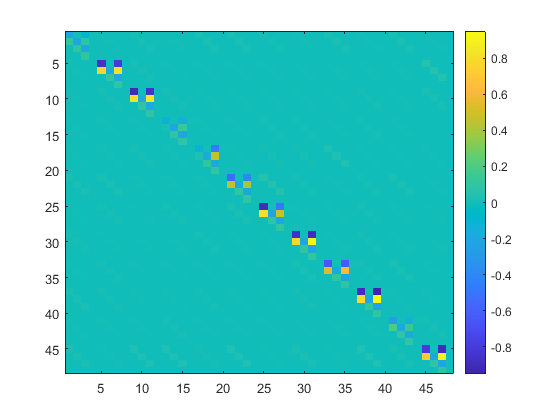


% Linearization
epsX = 10^-9;
epsU = 10^-9;
doCellOps = 1;   % Flag for LINEARIZEF
[A, B] = LINEARIZEF('EVALF',x0,p,u0,epsX,epsU,doCellOps);

% Plot Jacobians
figure(1);
imagesc(A);
colorbar;

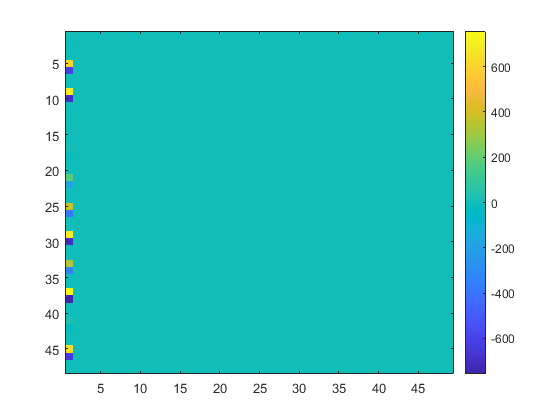

figure(2);
imagesc(B);
colorbar;


% Condition #'s
cA = condest(A);

% LU solver w/o conditioning
disp('No Conditioning')

No Conditioning


fprintf('Condition Number: %d', cA)

Condition Number: 2.870038e+05

% BVec = cell2vec(u0,1);
BVec = zeros(4*P,1);
tic
disp('LU')

LU


x1 = A \ (-B*[1;BVec])

x1 =           380.580453692909
          246.503793829804
           140.06098556352
          138336.482405642
          693.170442234343
          125.367104142036
          113.560160896171
          114144.857413347
          842.425975712429
         -49.7787917347005


toc

Elapsed time is 0.007526 seconds.



% GMRES w/o conditioning
tol = 1e-4;
maxit = size(A,1);
tic 
disp('GMRES')

GMRES


x2 = gmres(A, -B*[1;BVec],[],tol,maxit)

gmres converged at iteration 41 to a solution with relative residual 1.3e-05.


x2 =           380.428146182069
          246.529238137119
          140.136130016614
          138537.288313177
          693.248669611965
          125.241240077347
           113.47150545999
          114071.768145129
          842.446802354918
          -49.855271918512


toc

Elapsed time is 0.009466 seconds.



% LU solver w/ diagonal scaling
disp('Diagonal Scaling')

Diagonal Scaling


disp('LU')

LU


sf = 10^10;
diagA = sf*diag(A);
A_scaled = A;
A_scaled(1:size(A,1)+1:end) = diagA;
cA_ds = condest(A_scaled);
fprintf('Condition Number: %d', cA_ds)

Condition Number: 9.052571e+03

tic
x3 = (A_scaled \ (-sf*B*[1;BVec]))

x3 =            43.935313188951
         -45.9312863470462
        -0.153836081317352
           7.8300846028593
          719.951933341417
         -3254.18792669609
       -0.0333165021794904
         -15.5500475642064
          774.884596576407
         -3946.59208029783


toc

Elapsed time is 0.007055 seconds.



% GMRES with diagonal scaling
disp('GMRES')

GMRES


tic
x4 = gmres(A_scaled, -sf*B*[1;BVec],[],tol,maxit)

gmres converged at iteration 10 to a solution with relative residual 3.5e-05.


x4 =           43.9391969649178
         -45.9284550986229
        -0.153826598709868
        0.0246615476937659
          719.959085971058
          -3253.8888881513
        -0.033313436472166
       -0.0481181386530193
          774.873848643774
         -3946.72981808956


toc

Elapsed time is 0.008869 seconds.



% Jacobi preconditioner
disp('Jacobi')

Jacobi


pc = zeros(size(A,1),size(A,2));
pc(1:size(A,1)+1:end) = 1./diagA; % Invert
A_jcb = pc*A;
cA_jcb = condest(A_jcb);
fprintf('Condition Number: %d', cA_jcb)

Condition Number: 8.173297e+07

disp('LU')

LU


x5 = (A_jcb \ (-pc*B*[1;BVec]))

x5 =           380.580453692906
          246.503793829802
          140.060985563519
          138336.482405641
          693.170442234346
          125.367104142033
          113.560160896168
          114144.857413344
          842.425975712432
         -49.7787917347053


disp('GMRES')

GMRES


x6 = gmres(A_jcb, -pc*B*[1;BVec],[],tol,maxit)

gmres converged at iteration 41 to a solution with relative residual 6.9e-05.


x6 =           379.882736715287
          246.170113849461
          139.947141660384
          138224.046554245
          693.072416531197
          125.401768015043
          113.654315776126
          114239.509992245
          842.263921233042
         -49.6773585293104



% MATLAB equilibrate preconditioner
disp('Equilibrate')

Equilibrate


[P,R,C] = equilibrate(A);
A_equi = R*P*A*C;
cA_equi = condest(A_equi);
fprintf('Condition Number: %d', cA_equi)

Condition Number: 1.410232e+03

disp('LU')

LU


x7 = (A_equi \ (-R*P*B*[1;BVec]))

x7 =           380.580453692915
          246.503793829805
          140.060985563519
          140.068913706751
          693.170442234339
          66.3264650663515
          113.560160896175
          113.544692609557
          842.425975712429
         -28.2034403661916


disp('GMRES')

GMRES


x8 = gmres(A_equi,-R*P*B*[1;BVec],[],tol,maxit)

gmres converged at iteration 40 to a solution with relative residual 7.8e-05.


x8 =           382.205568244107
          246.888373202192
          140.030605025825
          140.009678507614
           692.18413285327
          66.9269837176045
          114.589343019371
           114.56500947454
          841.979043235576
         -27.8487710058361
